imfinfo('peppers.png')

ans = struct with fields:
                  Filename: '/Users/marci/Documents/MATLAB/DVS-labs/lab-2/peppers.png'
               FileModDate: '08-Jan-2026 12:39:03'
                  FileSize: 711722
                    Format: 'png'
             FormatVersion: []
                     Width: 777
                    Height: 584
                  BitDepth: 24
                 ColorType: 'truecolor'
           FormatSignature: [137 80 78 71 13 10 26 10]
                  Colormap: []
                 Histogram: []
             InterlaceType: 'none'
              Transparency: 'alpha'
    SimpleTransparencyData: []
           BackgroundColor: []
           RenderingIntent: []
            Chromaticities: []
                     Gamma: []
               XResolution: []
               YResolution: []
            ResolutionUnit: []
                   XOffset: []
                   YOffset: []
                OffsetUnit: []
           SignificantBits: []
              ImageModTime: []
          

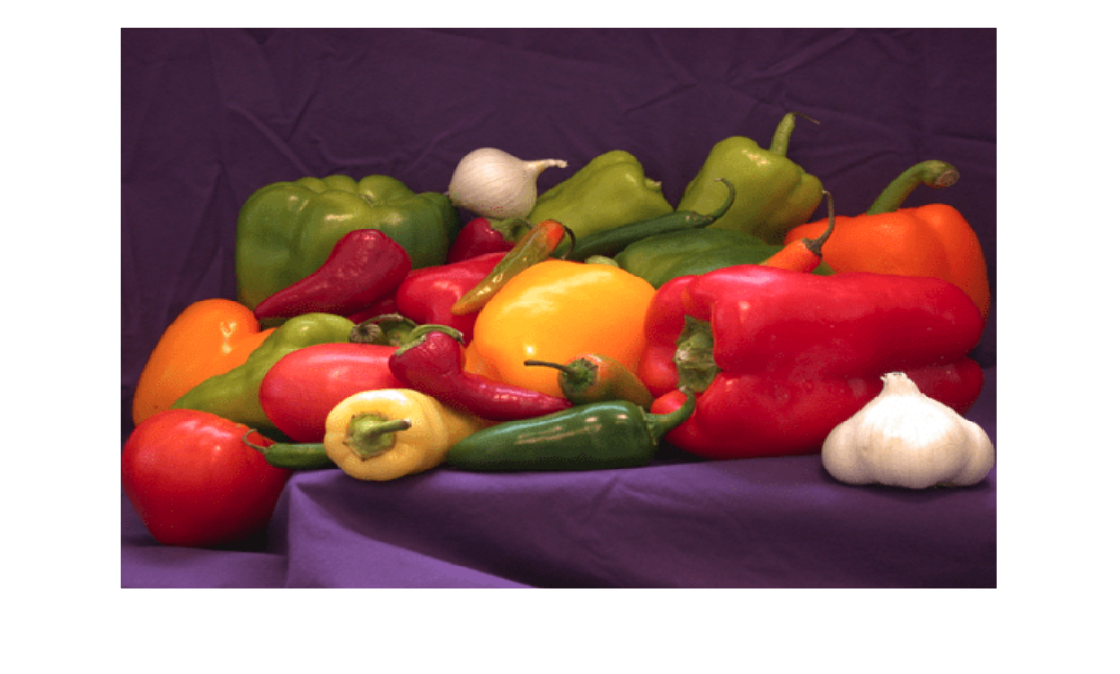

RGB = imread('peppers.png');  
imshow(RGB) 

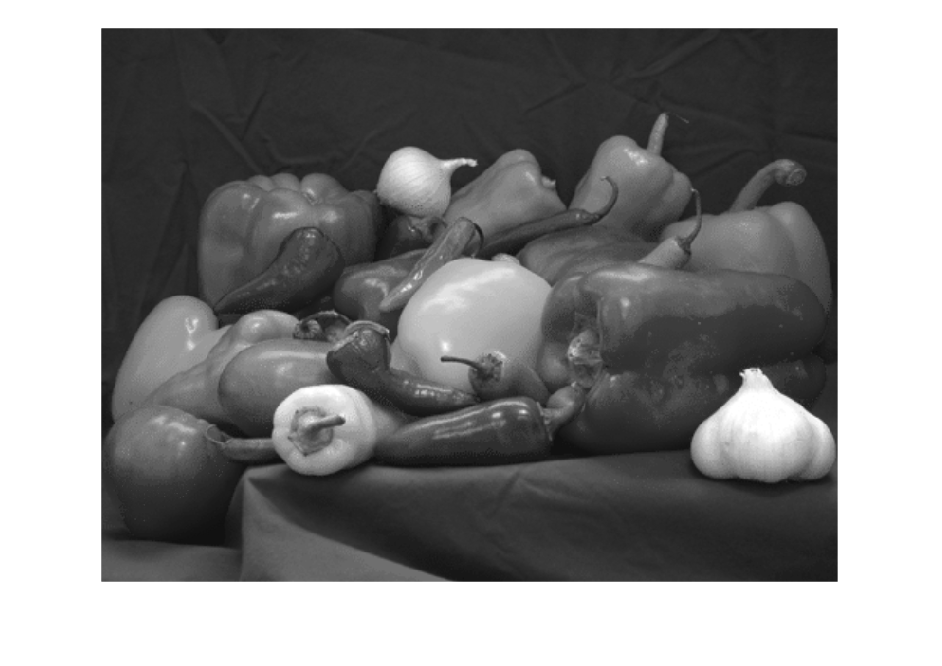

I = rgb2gray(RGB);
figure              % start a new figure window
imshow(I)

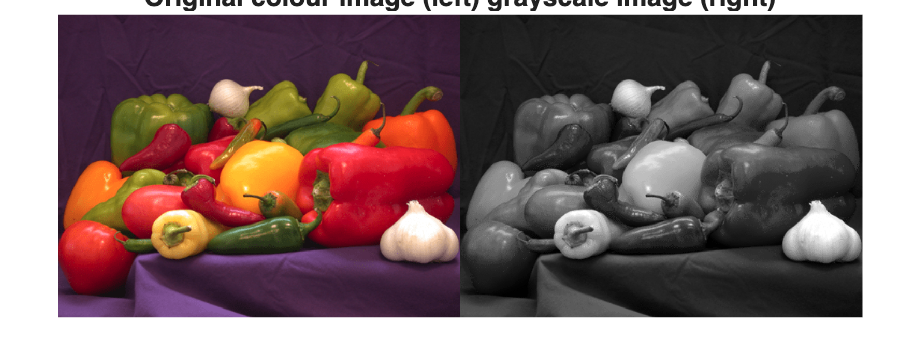


imshowpair(RGB, I, 'montage')
title('Original colour image (left) grayscale image (right)');

# Task 11 - Splitting an RGB image into separate channels

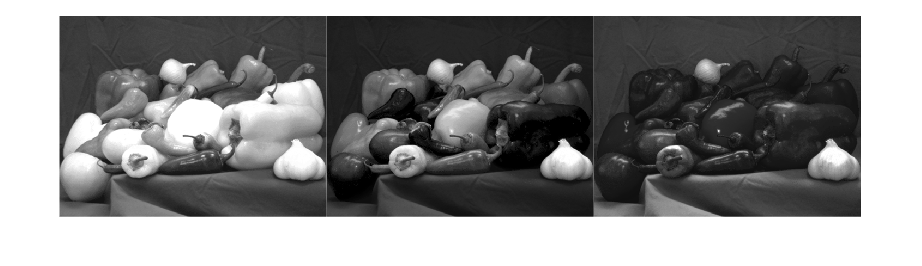

[R,G,B] = imsplit(RGB);
montage({R, G, B},'Size',[1 3])

dfdg

# Task 12 - Map RGB image to HSV space and into separate channels

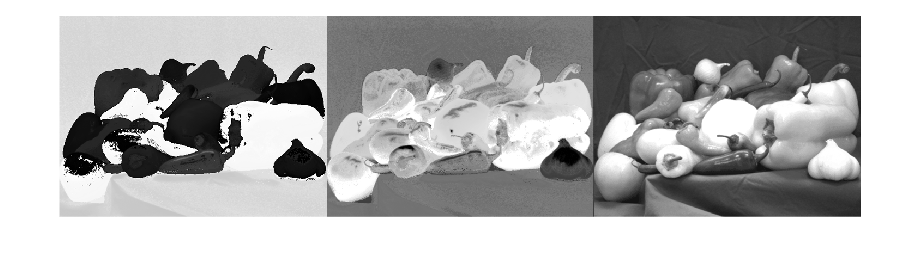

HSV = rgb2hsv(RGB);
[H,S,V] = imsplit(HSV);
montage({H,S,V}, 'Size', [1 3])

Hue

Saturation

Value

# Task 13 - Map RGB image to XYZ space

Map the RGB image to the XYZ colour space with the rgb2xyz( ) function

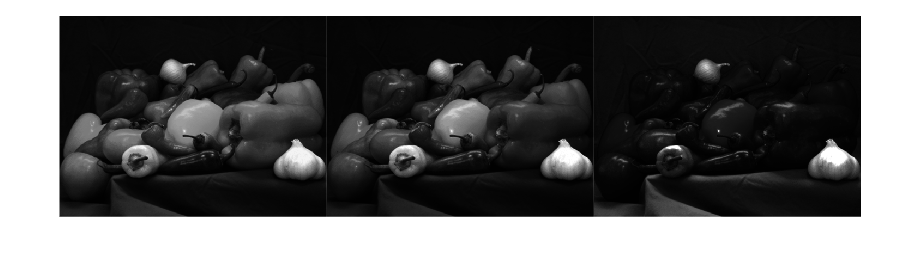

XYZ = rgb2xyz(RGB);
[X,Y,Z] = imsplit(XYZ);
montage({X,Y,Z}, 'Size', [1 3])

> Need a refresher of what X,Y, Z represents in colour space